# Real time penstrokes scanning Algorithm explained.

## SECTION 1: IMPORTING IMAGES

The following script will import two consecutive video frames as image_1 and image_2. 

If you have opened this file as a live script in Matlab, **Click in the code below** and press **Ctrl+Enter** so as to run this section.

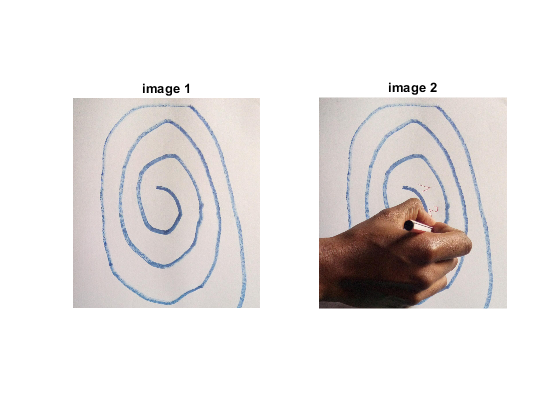

image_1=imread('images1.jpg');
image_2=imread('images2.jpg');
subplot(1,2,1)
imshow(image_1)
title('image 1')
subplot(1,2,2)
imshow(image_2)
title('image 2')

## SECTION 2: IMAGE ENHANCEMENT

The following script will Enhance image_1 and image_2, using a function "Efilter" which we defined (check if you have Efilter.m in the current directory).

If you have opened this file as a live script in Matlab, **Click in the code below** and press **Ctrl+Enter** so as to run this section.

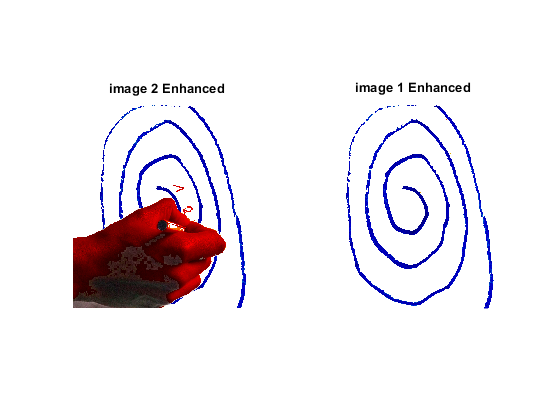

image_1=Efilter(image_1,1.65);
image_2=Efilter(image_2,1.65);
subplot(1,2,1)
imshow(image_2)
title('image 2 Enhanced')
subplot(1,2,2)
imshow(image_1)
title('image 1 Enhanced')

## SECTION 3: MASK CREATION

The following script will threshold image_2, so as to create an RGB mask called **"imageMask3"** (3 indicates that it is a mask for 3-dimensitonal image: Red, Green and Blue image).

It will create also the binary complementary of "imageMask3" which is called **"Compl_Mask3"**

If you have opened this file as a live script in Matlab, **Click in the code below** and press **Ctrl+Enter** so as to run this section.

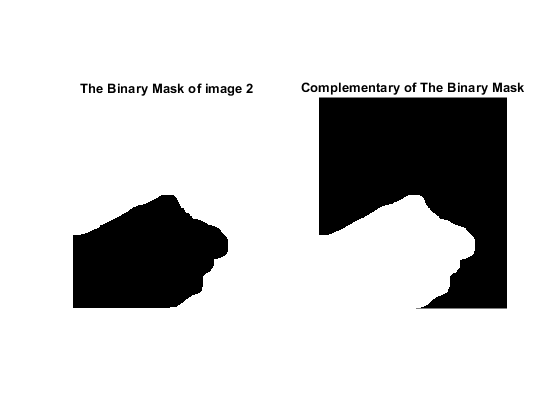

image_gray=rgb2gray(image_2);
t=254/255;
image_bin=imbinarize(image_gray,t);
image_dil=imdilate(image_bin,ones(29));
image_eroded=imerode(image_dil,ones(65));
imageMask=uint8(image_eroded);

imageMask3(:,:,1)=imageMask;
imageMask3(:,:,2)=imageMask;
imageMask3(:,:,3)=imageMask;
Compl_Mask3=(~imageMask3);
subplot(1,2,1)
imshow(imageMask3*255)
title('The Binary Mask of image 2')
subplot(1,2,2)
imshow(Compl_Mask3*255)
title('Complementary of The Binary Mask')

## SECTION 4: SEGMENTATION

The following script will segment image_2 by doing the element-wise multiplication with the created mask: 

**Part_1=image_2 .* uint8(imageMask3)**

The following script will also segment image_1 by doing the element-wise multiplication with the created mask: 

**Part_2=image_1 .* uint8(Compl_Mask3);**

as you see, the segmented images are saved in variables: Part_1 and Part_2.

If you have opened this file as a live script in Matlab, **Click in the code below** and press **Ctrl+Enter** so as to run this section.

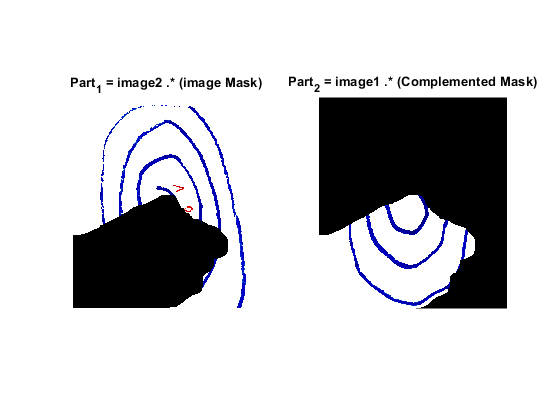

Part_1=image_2 .* uint8(imageMask3);
Part_2=image_1 .* uint8(Compl_Mask3);
subplot(1,2,1)
imshow(Part_1)
title('Part_1 = image2 .* (image Mask)')
subplot(1,2,2)
imshow(Part_2)
title('Part_2 = image1 .* (Complemented Mask)')

## SECTION 5: FINALIZING

This is the last step, where the final image will be the result of the removal of obstruction from image_2. This will be got through adding Part_1 to Part_2.

If you have opened this file as a live script in Matlab, **Click in the code below** and press **Ctrl+Enter** so as to run this section.

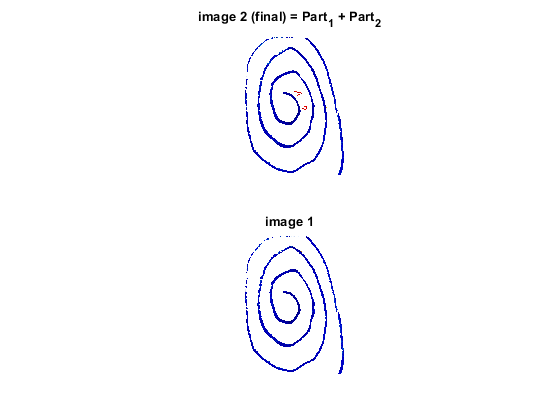

image_2_final=Part_1+Part_2;
subplot(2,1,1)
imshow(image_2_final)
title('image 2 (final) = Part_1 + Part_2')
subplot(2,1,2)
imshow(image_1)
title('image 1')